% Cluster visualization
% results are shown by : T-SNE, Minimal spanning tree, Histogram charts
% positions of each cell cluster on all H&E Images
% Author: Chang Lu
% luchang4104@gmail.com

clear all

% you can put your data folder under 'data' 
currentFolder = pwd;

datapath = '/Users/changlu/DATA/OLIVIA/PRG4'; % your own data path
% datapath = '/Volumes/My Passport/synchronization/colleagues/Elias/data';

addpath(genpath('fun'));

files=dir(fullfile(datapath));
isub = [files(:).isdir];
fileNames={files(isub).name}';
fileNames(ismember(fileNames,{'.','..','results'})) = [];


##  load data

%check the mat files in the datapath
clusterfilename = 'cosine_kmedoids_k=10';
datamatname = 'cellmarker_rescale_intergration_t=3';

load([datapath,filesep,clusterfilename]); % clustering results
load([datapath,filesep, datamatname]);

## result save path

directoryresult = [datapath,filesep,'results',filesep, datamatname, clusterfilename,filesep];
if ~exist(directoryresult,'dir')
    mkdir(directoryresult);
end


biomarker_name = extractAfter(biomarkername, "_");
global clr
vColor = labels;
unqValues = unique(vColor);
clr = distinguishable_colors(numel(unqValues));

tsnemat=tsne_cos;
inten=norm_inten;

%% number of cell per cluster
TABLE = tabulate(labels);
T = array2table(TABLE);
T.Properties.VariableNames(1:3) = {'Cluster','count','percentage'};
filename = fullfile(directoryresult, 'cellcountpercluster.xlsx');
writetable(T,filename);


%% number of cell per folder
TABLE2 = tabulate(foldername);
T = array2table(TABLE2);
T.Properties.VariableNames(1:3) = {'Cluster','count','percentage'};
filename = fullfile(directoryresult, 'cellcountperfolder.xlsx');
writetable(T,filename);

## number of cell per cluster in each folder

bindtable = [labels,foldername];
for i = 1:length(nuancename)
   tablei =  tabulate(bindtable(bindtable(:,2)==nuancename{i},1));
%    output = [header; tablei];
   T = array2table(tablei);
   T.Properties.VariableNames(1:3) = {'Cluster','count','percentage'};
   filename = fullfile(directoryresult, 'cell_count_percluster_in_each_folder.xlsx');
   writetable(T,filename,'Sheet',nuancename{i});
end



## MST

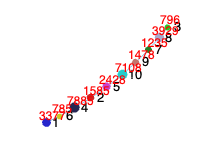


% h = draw_SPADE_tree(labels,centers,'cosine',[],[]);
% h = draw_mst_new(labels,centers,similarity,color, shownum )
h = draw_mst_new(labels,centers,'cosine',[],'T');
print(gcf,'-dpng',[directoryresult,'MST.jpg']);

## tsne

name = [clustername,' tsne cluster'];
colors = jet(length(unique(labels)));

figure; gscatter(tsnemat(:,1),tsnemat(:,2),labels, colors )
% fig = draw_tsne(tsnemat,labels, []);
print(gcf,'-dpng',[directoryresult,name,'.jpg']);

% foldername = [];
% for i = 1:length(begin_idx)-1
%     foldername = [foldername;string(repmat(nuancename{i},begin_idx(i+1)-begin_idx(i),1))];
% end
% name = [clustername,' tsne folder'];
% figure; gscatter(tsnemat(:,1),tsnemat(:,2),foldername, colors )
% print(gcf,'-dpng',[directory,name,'.jpg']);

## polar histogram

filename = [directoryresult,clustername,'histogram'];
draw_Polar_fig(labels,centers,biomarker_name,filename,[]);

## H&E

clus=unique(labels');
color = [255,0,0];
plaquesname= nuancename;
for cl=1:length(clus)
    c_name = num2str(clus(cl));
    for i= 1:length(plaquesname)
        draw_several_clusters_on_allimgsinglefig(labels,plaquesname{i},nuancename,{cl},mix_pos,begin_idx,datapath,directoryresult,color,c_name);
    end
end